% Read CSV as text to preserve hex values
opts = detectImportOptions('Standard_Setup_1.csv');
opts = setvartype(opts, 'char');   % all columns as text
rawData = readtable('Standard_Setup_1.csv', opts);

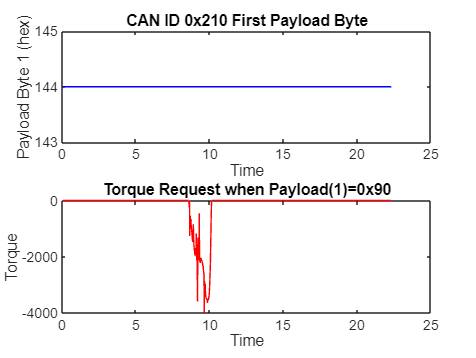


% Skip header (first 7 rows)
rawData = rawData(8:end,:);

% Convert relevant columns
time  = str2double(rawData{:,1});             % timestamp
canID = hex2dec(rawData{:,3});                % CAN ID in decimal
payloadByte1 = hex2dec(rawData{:,6});         % first payload byte
lsbByte      = hex2dec(rawData{:,7});         % second payload byte
msbByte      = hex2dec(rawData{:,8});         % third payload byte

% Filter ID = 0x210
idx210 = (canID == hex2dec('210'));
time210 = time(idx210);
payload210 = payloadByte1(idx210);
lsb210     = lsbByte(idx210);
msb210     = msbByte(idx210);

% Filter torque messages (first payload byte = 0x90)
idxTorque = (payload210 == hex2dec('90'));
timeTorque = time210(idxTorque);

%big endian
msb = lsb210(idxTorque);
lsb = msb210(idxTorque);

%litle endian
lsb = lsb210(idxTorque);
msb = msb210(idxTorque);

% Combine little-endian 16-bit
torque16u = bitor(uint16(lsb), bitshift(uint16(msb),8));

% Interpret as signed int16
torque16 = typecast(torque16u, 'int16');

% --- Plot ---
figure;

subplot(2,1,1);
plot(time210, payload210, 'b');
xlabel('Time');
ylabel('Payload Byte 1 (hex)');
title('CAN ID 0x210 First Payload Byte');

subplot(2,1,2);
plot(timeTorque, double(torque16), 'r');
xlabel('Time');
ylabel('Torque');
title('Torque Request when Payload(1)=0x90');

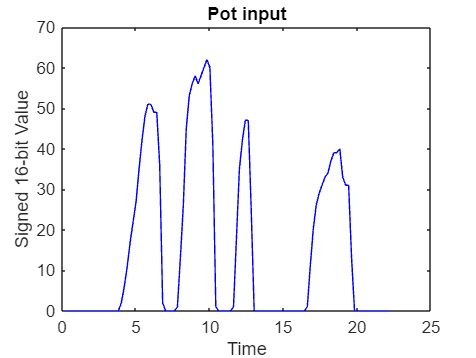


% --- Filter ID = 9 ---
idx9 = (canID == 9);
time9 = time(idx9);

% Grab payload bytes 6 and 7 (columns 11 and 12)
lsb9 = hex2dec(rawData{idx9,12});  % byte 6
msb9 = hex2dec(rawData{idx9,13});  % byte 7

% big endian 
value16u = bitor(uint16(msb9), bitshift(uint16(lsb9),8));
value16  = typecast(value16u, 'int16');


% --- Plot ---
figure;

plot(time9, value16, 'b');
xlabel('Time');
ylabel('Signed 16-bit Value');
title('Pot input');



% Prepare 2xN matrix: first row = time, second row = data
Pot_input = [time9'; transpose(msb9)];

% Save as .mat file for Simulink
save('Pot_input.mat', 'Pot_input');

% Read CSV as text to preserve hex values
opts = detectImportOptions('Standard_Setup_1.csv');
opts = setvartype(opts, 'char');   % all columns as text
rawData = readtable('Standard_Setup_1.csv', opts);

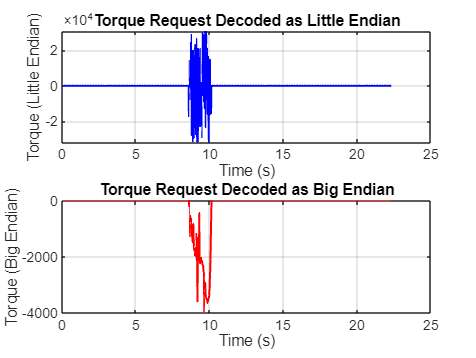


% Skip header (first 7 rows)
rawData = rawData(8:end,:);

% Convert relevant columns
time  = str2double(rawData{:,1});     % timestamp
canID = hex2dec(rawData{:,3});        % CAN ID
byte0 = hex2dec(rawData{:,6});        % Payload byte 0
byte1 = hex2dec(rawData{:,7});        % Payload byte 1
byte2 = hex2dec(rawData{:,8});        % Payload byte 2

% --- Filter for CAN ID = 0x210 ---
mask210 = (canID == hex2dec('210'));
time210 = time(mask210);
byte0_210 = byte0(mask210);
byte1_210 = byte1(mask210);
byte2_210 = byte2(mask210);

% --- Filter torque request messages (first payload byte = 0x90) ---
maskTorque = (byte0_210 == hex2dec('90'));
timeTorque = time210(maskTorque);
byte1_torque = byte1_210(maskTorque);
byte2_torque = byte2_210(maskTorque);

% --- Decode as Little Endian ---
lsb_little = byte1_torque;
msb_little = byte2_torque;
torqueLittle_u16 = bitor(uint16(lsb_little), bitshift(uint16(msb_little), 8));
torqueLittle = typecast(torqueLittle_u16, 'int16');

% --- Decode as Big Endian ---
msb_big = byte1_torque;
lsb_big = byte2_torque;
torqueBig_u16 = bitor(uint16(lsb_big), bitshift(uint16(msb_big), 8));
torqueBig = typecast(torqueBig_u16, 'int16');

% --- Plot comparison ---
figure;
subplot(2,1,1);
plot(timeTorque, double(torqueLittle), 'b', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Torque (Little Endian)');
title('Torque Request Decoded as Little Endian');
grid on;

subplot(2,1,2);
plot(timeTorque, double(torqueBig), 'r', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Torque (Big Endian)');
title('Torque Request Decoded as Big Endian');
grid on;

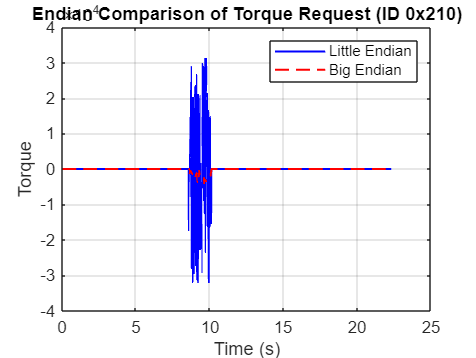


% --- Optional: Overlay comparison on one plot ---
figure;
plot(timeTorque, double(torqueLittle), 'b', 'LineWidth', 1.2); hold on;
plot(timeTorque, double(torqueBig), 'r--', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Torque');
title('Endian Comparison of Torque Request (ID 0x210)');
legend('Little Endian', 'Big Endian');
grid on;